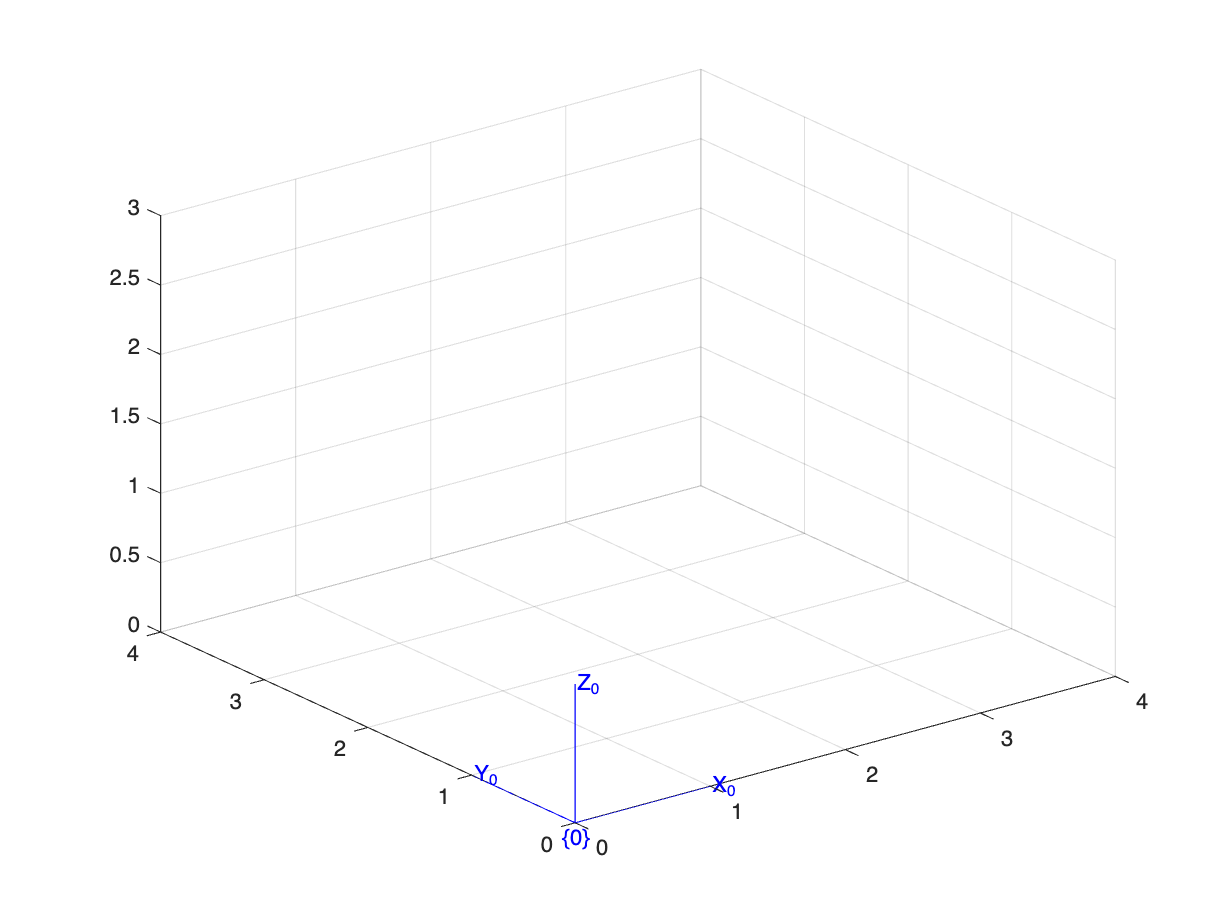

%3.1

% Create a new figure
figure;

% Plot the default 3D coordinate frame {0}
hold on;
trplot(eye(3), 'frame', '0', 'color', 'b');  % Identity matrix for frame {0}

% Limit the plot area for X, Y, and Z to [-1, 2]
axis([0 4 0 4 0 3]);

% Enable the grid
grid on;
view(3)

% 3.2

R_0_in_1 = eye(3)*rotz(pi/2)

R_0_in_1 =      0    -1     0
     1     0     0
     0     0     1


t_0_in_1 = [2;3;1]

t_0_in_1 =      2
     3
     1


q_in_0 = [2;3;1]

q_in_0 =      2
     3
     1


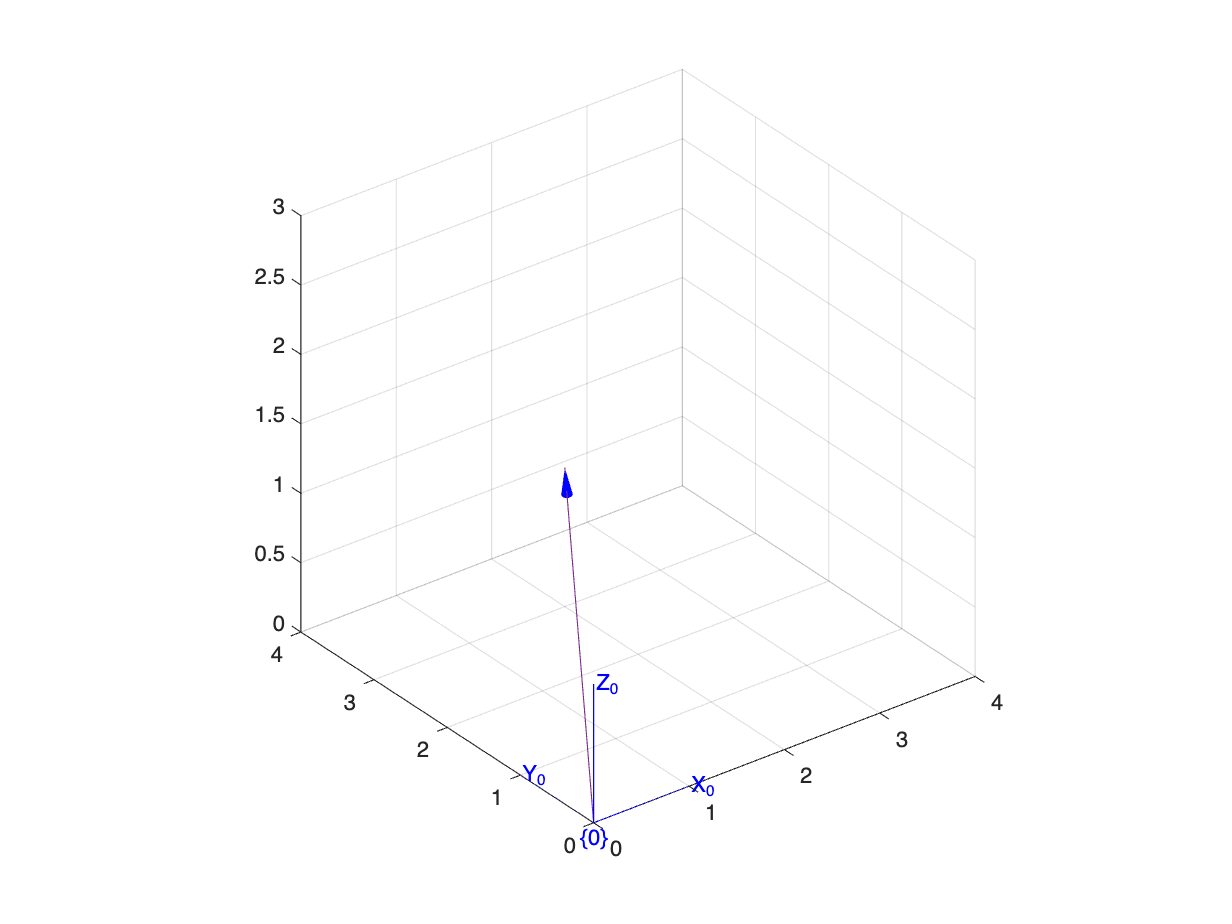

% 3.3

plot_arrow([0,0,0],[2,3,1], 'b')

% 3.4

H_0_in_1 = rt2tr(R_0_in_1,t_0_in_1)

H_0_in_1 =      0    -1     0     2
     1     0     0     3
     0     0     1     1
     0     0     0     1


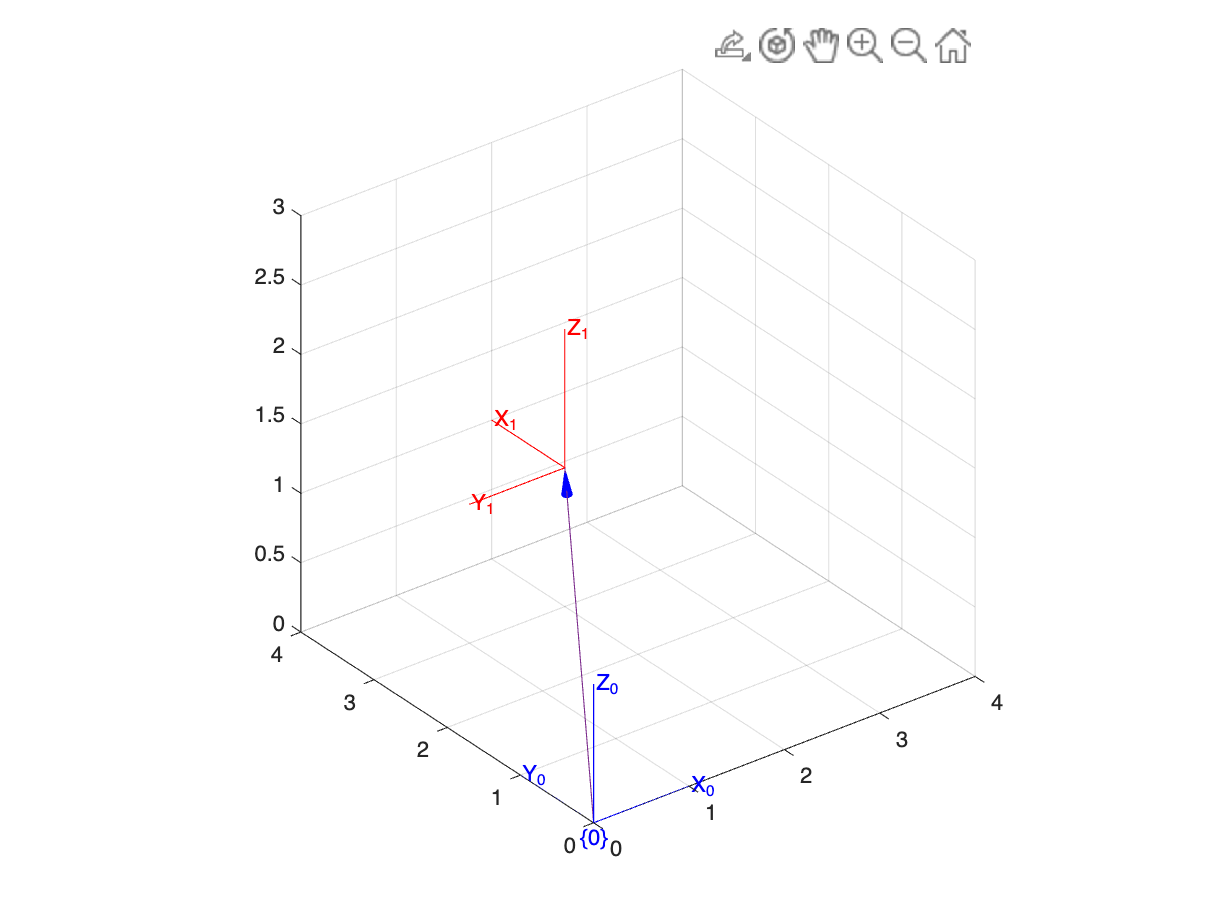


% Plot the default 3D coordinate frame {0}
hold on;
trplot(H_0_in_1, 'frame', '1', 'color', 'r');  % Identity matrix for frame {1}

% Limit the plot area for X, Y, and Z to [-1, 2]
axis([0 4 0 4 0 3]);

% Enable the grid
grid on;
view(3)

% 3.5

p_in_1 = [1;1;1]

p_in_1 =      1
     1
     1


p_1_in_0 = H_0_in_1*e2h(p_in_1)

p_1_in_0 =      1
     4
     2
     1


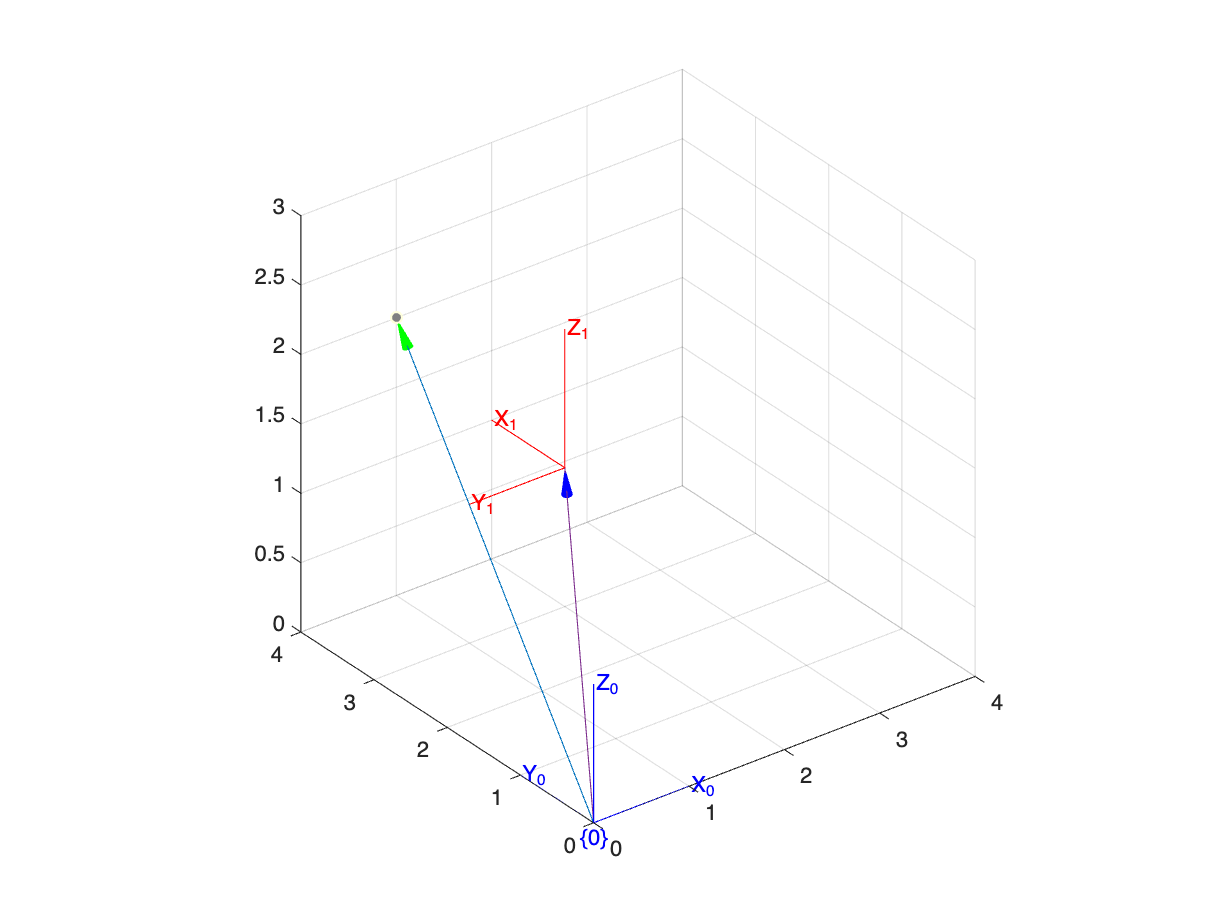


plot_arrow([0,0,0],h2e(p_1_in_0), 'g')

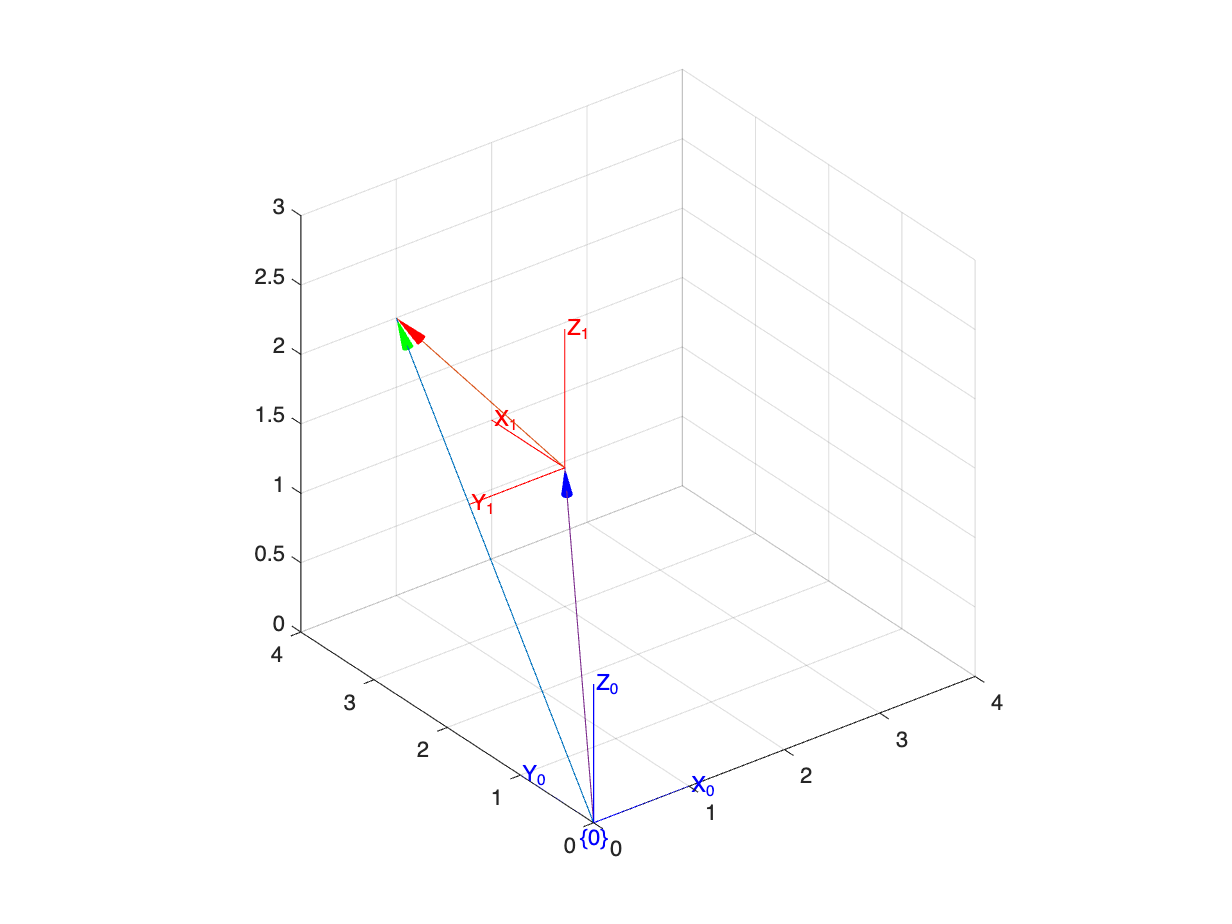

% 3.6

plot_arrow([2,3,1],h2e(p_1_in_0), 'r')

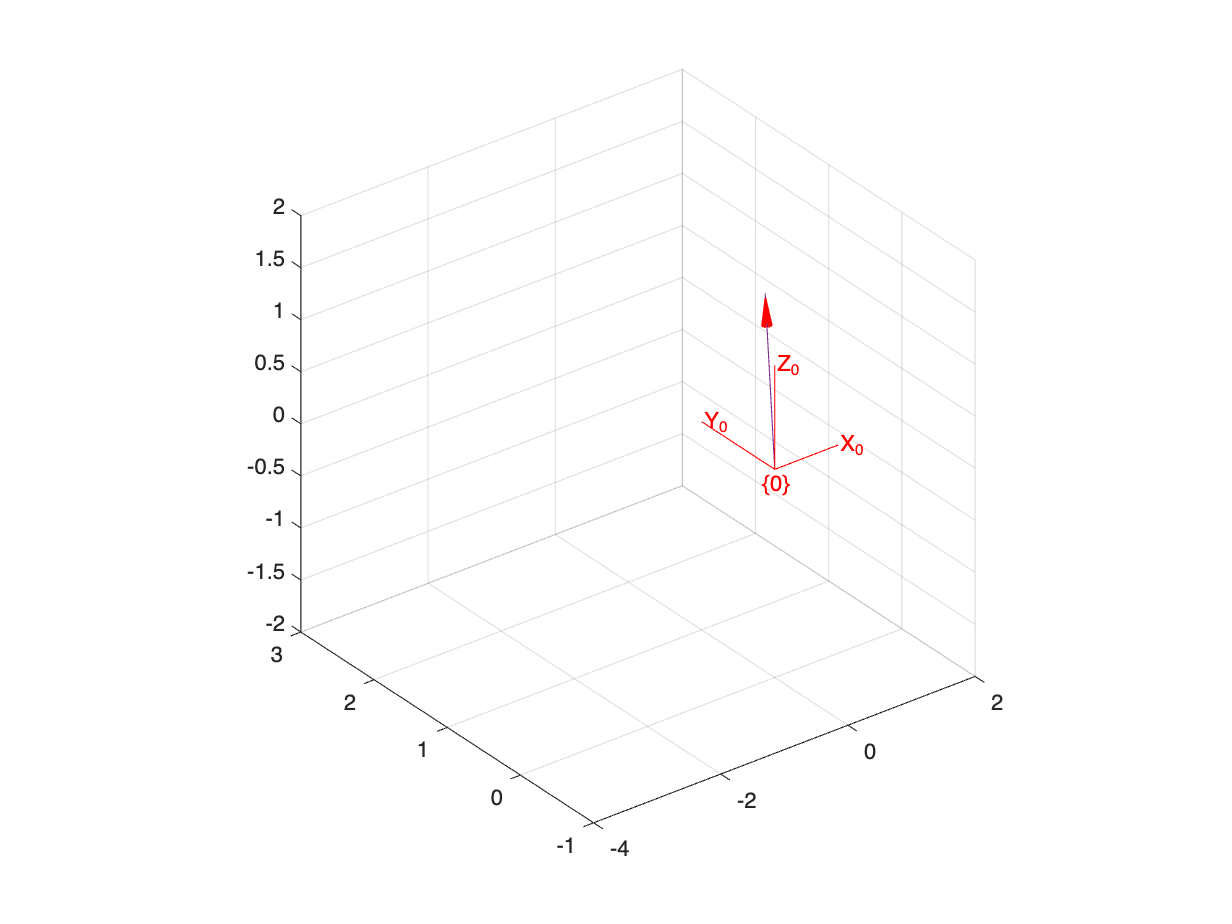

% 3.7

% Create a new figure
figure;

% Plot the default 3D coordinate frame {0}
hold on;
trplot(eye(3), 'frame', '0', 'color', 'r');  % Identity matrix for frame {0}

% Limit the plot area for X, Y, and Z to [-1, 2]
axis([-4 2 -1 3 -2 2]);

% Enable the grid
grid on;
view(3)

plot_arrow([0,0,0],[1,1,1], 'r')

% 3.8

H_1_in_0 = inv(H_0_in_1)

H_1_in_0 =      0     1     0    -3
    -1     0     0     2
     0     0     1    -1
     0     0     0     1


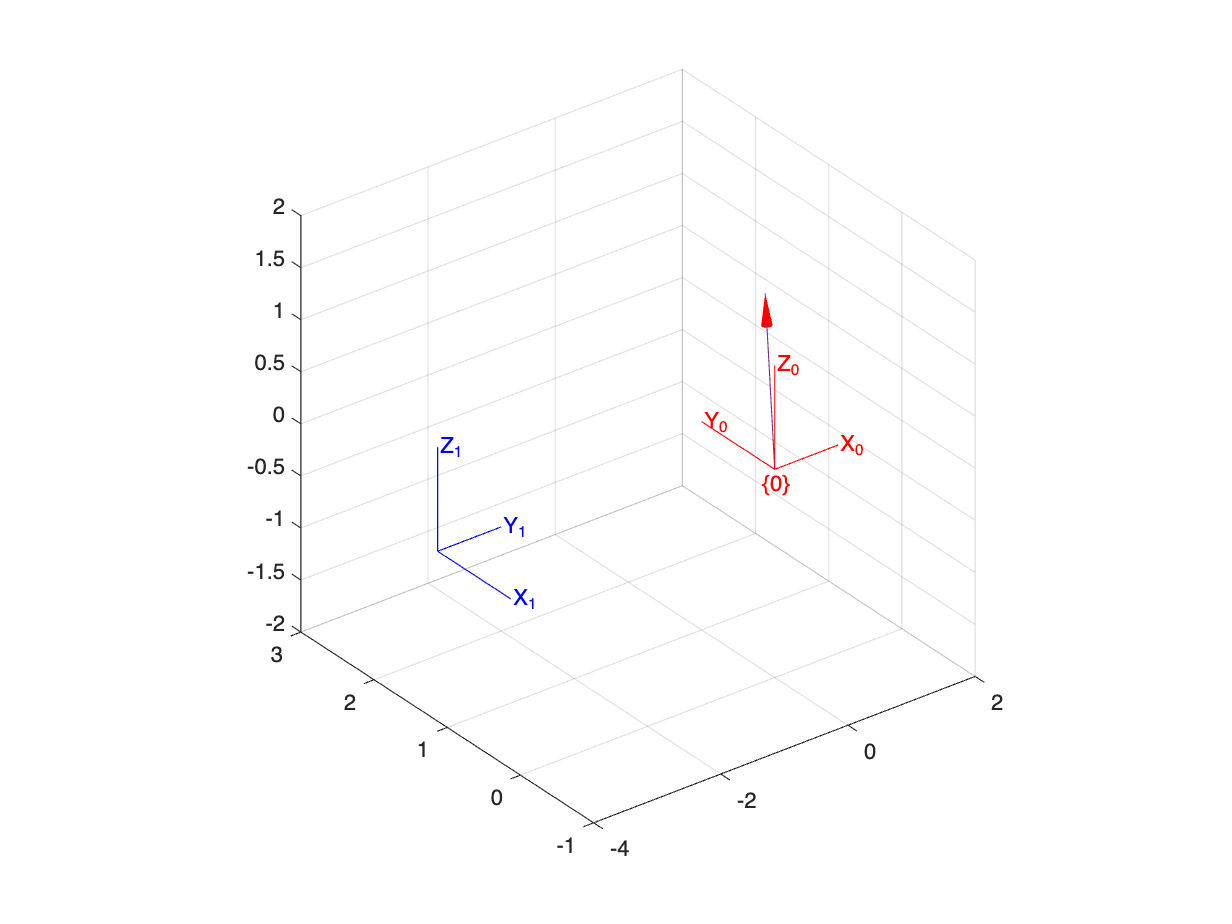

% 3.9

% Plot the default 3D coordinate frame {0}
hold on;
trplot(H_1_in_0, 'frame', '1', 'color', 'b');  % Identity matrix for frame {1}

% Limit the plot area for X, Y, and Z to [-1, 2]
axis([-4 2 -1 3 -2 2]);

% Enable the grid
grid on;
view(3)

% 3.10
t_1_in_0 = H_1_in_0(1:3,4)

t_1_in_0 =     -3
     2
    -1


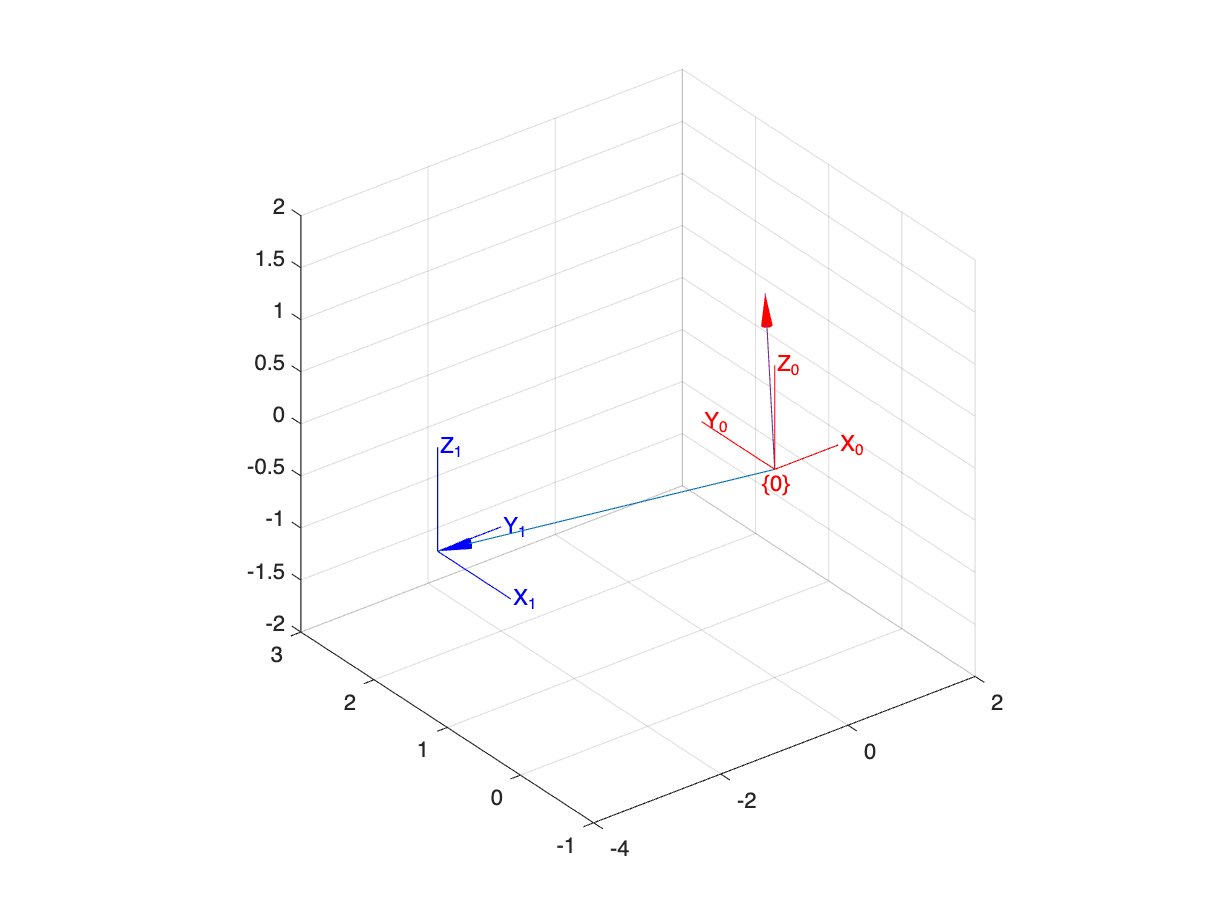


plot_arrow([0,0,0],t_1_in_0, 'b')

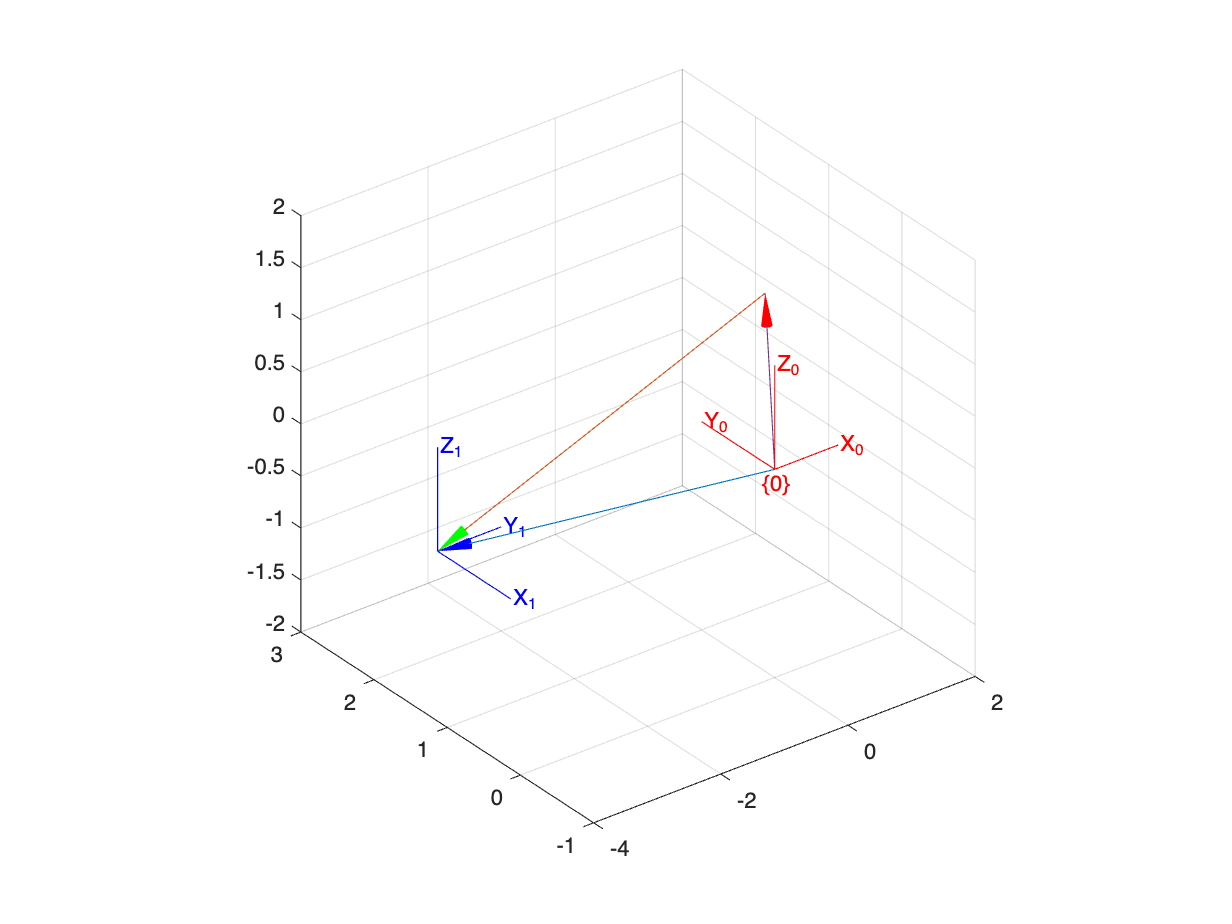

% 3.11
plot_arrow(p_in_1,t_1_in_0, 'g')

% 3.12
close all; 
clear all; 
figure;  
xlabel('x'); ylabel('y'); zlabel('z');   
trplot(eye(4),'color','b','frame','0','length',0.4,'thick',2);  
hold on; grid on; axis equal; 
axis([-2 2 0 2 0 3.5]); 
fill3([0 0 -1 -1],[1 2 2 1],[1 1 1 1],'g'); 
fill3([0 0 0 0 0 0 0 0],[1 1.1 1.1 1.9 1.9 2 2 1],[0 0 0.9 0.9 0 0 1 1],'g'); 
fill3([-1 -1 -1 -1 -1 -1 -1 -1],[1 1.1 1.1 1.9 1.9 2 2 1],[0 0 0.9 0.9 0 0 1 1],'g'); 
fill3([0 -0.1 -0.1 -0.9 -0.9 -1 -1 0],[2 2 2 2 2 2 2 2],[0 0 0.9 0.9 0 0 1 1],'g'); 
fill3([0 -0.1 -0.1 -0.9 -0.9 -1 -1 0],[1 1 1 1 1 1 1 1],[0 0 0.9 0.9 0 0 1 1],'g'); 
fill3([-0.4 -0.4 -0.6 -0.6],[1.4 1.6 1.6 1.4],[1 1 1 1],'r'); 
fill3([-0.4 -0.4 -0.6 -0.6],[1.4 1.6 1.6 1.4],[1.2 1.2 1.2 1.2],'r'); 
fill3([-0.4 -0.6 -0.6 -0.4],[1.6 1.6 1.6 1.6],[1 1 1.2 1.2],'r'); 
fill3([-0.4 -0.6 -0.6 -0.4],[1.4 1.4 1.4 1.4],[1 1 1.2 1.2],'r'); 
fill3([-0.4 -0.4 -0.4 -0.4],[1.4 1.6 1.6 1.4],[1 1 1.2 1.2],'r'); 
fill3([-0.6 -0.6 -0.6 -0.6],[1.4 1.6 1.6 1.4],[1 1 1.2 1.2],'r'); 
fill3([-0.4 -0.4 -0.6 -0.6],[1.4 1.6 1.6 1.4],[3 3 3 3],'b'); 
fill3([-0.4 -0.4 -0.6 -0.6],[1.4 1.6 1.6 1.4],[3.2 3.2 3.2 3.2],'b'); 
fill3([-0.4 -0.6 -0.6 -0.4],[1.6 1.6 1.6 1.6],[3 3 3.2 3.2],'b'); 
fill3([-0.4 -0.6 -0.6 -0.4],[1.4 1.4 1.4 1.4],[3 3 3.2 3.2],'b'); 
fill3([-0.4 -0.4 -0.4 -0.4],[1.4 1.6 1.6 1.4],[3 3 3.2 3.2],'b'); 
fill3([-0.6 -0.6 -0.6 -0.6],[1.4 1.6 1.6 1.4],[3 3 3.2 3.2],'b');

view(3)

T_1_in_0 = rt2tr(eye(3), [0,1,1])

T_1_in_0 =      1     0     0     0
     0     1     0     1
     0     0     1     1
     0     0     0     1


trplot(T_1_in_0, 'frame', '1', 'color', 'b');  % Identity matrix for frame {1}

T_2_in_0 = rt2tr(eye(3), [-0.5,1.5,1])

T_2_in_0 =     1.0000         0         0   -0.5000
         0    1.0000         0    1.5000
         0         0    1.0000    1.0000
         0         0         0    1.0000


trplot(T_2_in_0, 'frame', '2', 'color', 'b');  % Identity matrix for frame {1}

T_3_in_0 = rt2tr(roty(pi)*rotz(pi/2),[-0.5,1.5,3])

T_3_in_0 =          0    1.0000         0   -0.5000
    1.0000         0         0    1.5000
         0         0   -1.0000    3.0000
         0         0         0    1.0000


display(T_3_in_0)

T_3_in_0 =          0    1.0000         0   -0.5000
    1.0000         0         0    1.5000
         0         0   -1.0000    3.0000
         0         0         0    1.0000


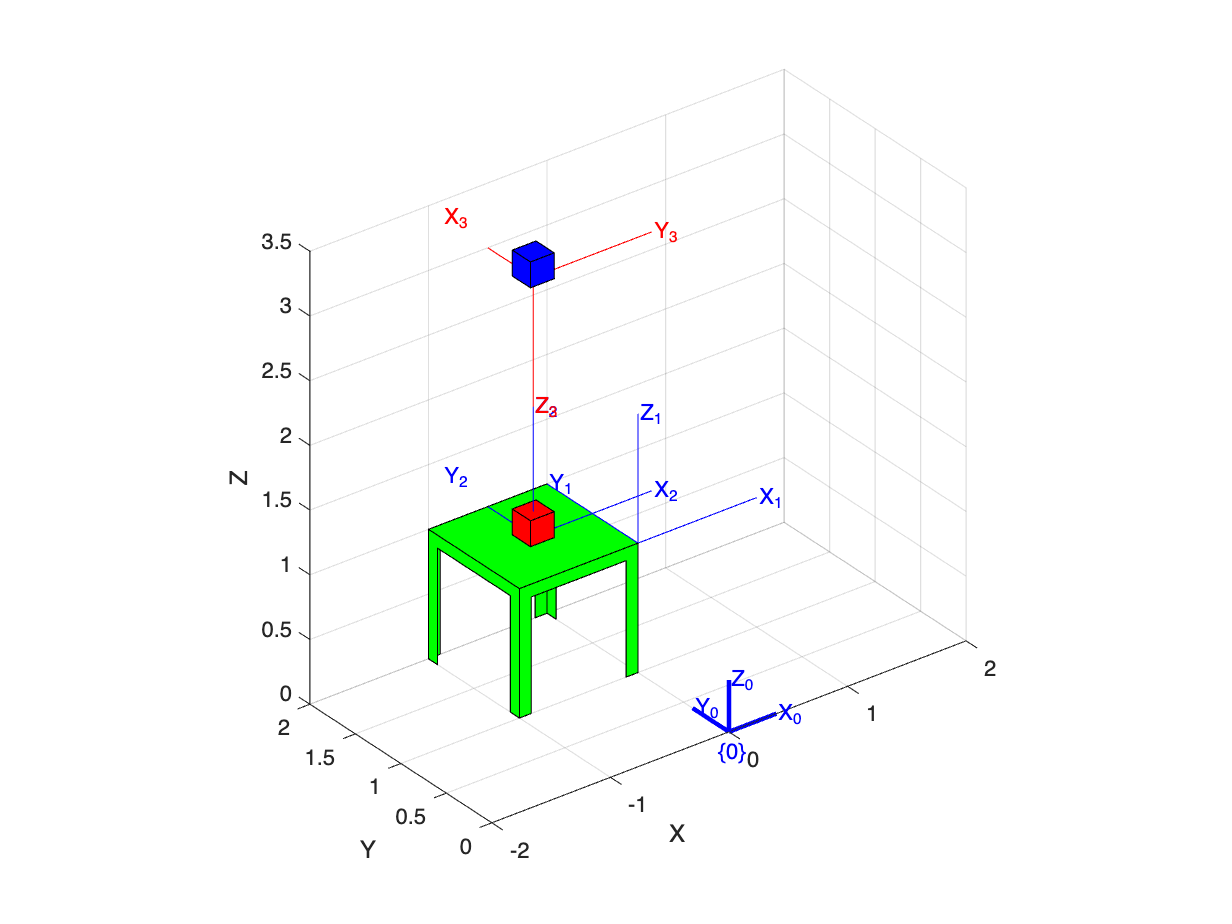

trplot(T_3_in_0, 'frame', '3', 'color', 'r');  % Identity matrix for frame {1}